# **E10.4**

## iii.

In this part we are tasked with implementing the LMS algorithm and run it for 40 steps for a stable learning rate value as obtained in part (ii) of this problem.

We will set $\alpha =0\ldotp 1$ for this problem.

In order to check for convergence, we will compare the squared errror with a convergence tolerance value which we have set to ${10}^{-9\;}$here.

% LMS Implementation
x_star = [0; 0];
x_hist = zeros([2, 41]);
x_hist(:, 1) = x_star;
error_hist = zeros([1, 40]);
num_steps = 40;
alpha = 0.1;
convergence_tol = 1e-9;
% repeat the two patterns 20 times to for 40 steps of the algorithm
patterns = [[1; 1], [-1; -1]];
targets = [1, -1];
num_repeats = num_steps / numel(targets);
inputs = repmat(patterns, [1, num_repeats]);
outputs = repmat(targets, [1, num_repeats]);
for iteration=1:num_steps
    iteration
    error = outputs(iteration) - x_star'*inputs(:, iteration)
    error_hist(iteration) = error^2;
    x_star = x_star + 2*alpha*error*inputs(:, iteration)
    x_hist(:, iteration+1) = x_star;
    if error_hist(iteration) < convergence_tol
        fprintf('#####\n\nConvergence reached at iteration %d.', iteration)
        error
        x_star
        break
    end
end

iteration = 1

error = 1

x_star =     0.2000
    0.2000


iteration = 2

error = -0.6000

x_star =     0.3200
    0.3200


iteration = 3

error = 0.3600

x_star =     0.3920
    0.3920


iteration = 4

error = -0.2160

x_star =     0.4352
    0.4352


iteration = 5

error = 0.1296

x_star =     0.4611
    0.4611


iteration = 6

error = -0.0778

x_star =     0.4767
    0.4767


iteration = 7

error = 0.0467

x_star =     0.4860
    0.4860


iteration = 8

error = -0.0280

x_star =     0.4916
    0.4916


iteration = 9

error = 0.0168

x_star =     0.4950
    0.4950


iteration = 10

error = -0.0101

x_star =     0.4970
    0.4970


iteration = 11

error = 0.0060

x_star =     0.4982
    0.4982


iteration = 12

error = -0.0036

x_star =     0.4989
    0.4989


iteration = 13

error = 0.0022

x_star =     0.4993
    0.4993


iteration = 14

error = -0.0013

x_star =     0.4996
    0.4996


iteration = 15

error = 7.8364e-04

x_star =     0.4998
    0.4998


iteration = 16

error = -4.7018e-04

x_star =     0.4999
    0.4999


iteration = 17

error = 2.8211e-04

x_star =     0.4999
    0.4999


iteration = 18

error = -1.6927e-04

x_star =     0.4999
    0.4999


iteration = 19

error = 1.0156e-04

x_star =     0.5000
    0.5000


iteration = 20

error = -6.0936e-05

x_star =     0.5000
    0.5000


iteration = 21

error = 3.6562e-05

x_star =     0.5000
    0.5000


iteration = 22

error = -2.1937e-05

x_star =     0.5000
    0.5000


#####

Convergence reached at iteration 22.

error = -2.1937e-05

x_star =     0.5000
    0.5000


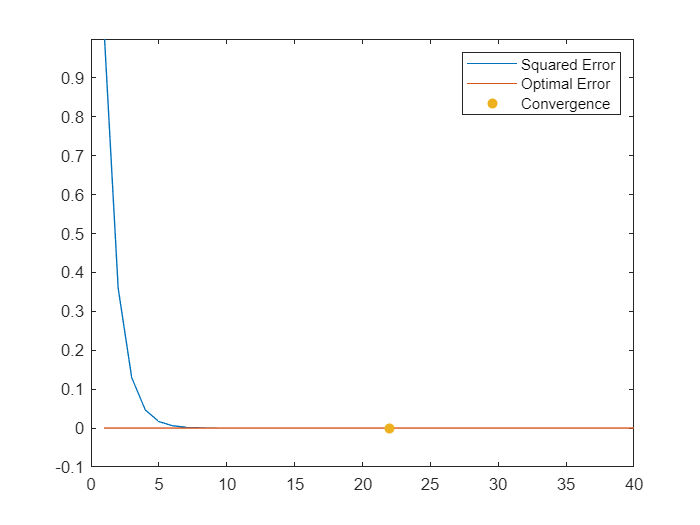

% plotting error history
plot(error_hist)
hold on
plot(zeros([1, 40]))
ylim([-0.1 max(error_hist)])
scatter(iteration, error_hist(iteration), 'filled')
legend('Squared Error', 'Optimal Error', 'Convergence')
hold off

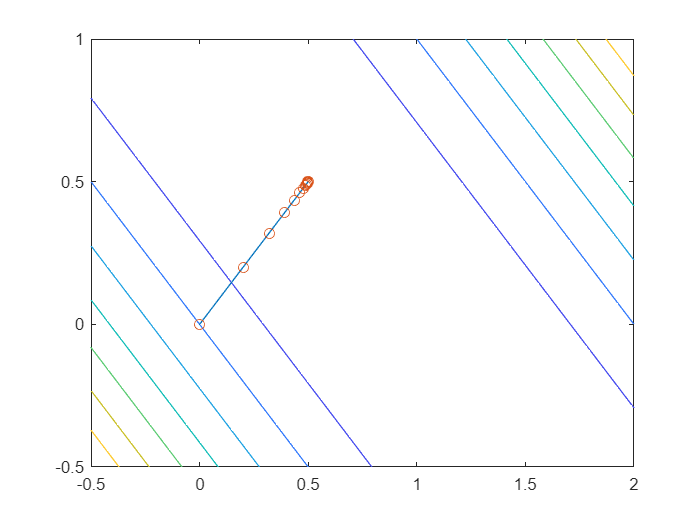

% sketching the trajectory on the contour plot
syms x1 x2 real
X = [x1; x2];
fx = 1 - 2*X'*[1; 1] + X'*[1 1; 1 1]*X;
fcontour(fx,[-0.5 2 -0.5 1])
hold on
plot(x_hist(1,:), x_hist(2,:));
hold on
scatter(x_hist(1,:), x_hist(2,:));
hold off

## iv.

Now we will run the same experiment but we will set $x_0 ={\left\lbrack 1,1\right\rbrack }^T$.

% LMS Implementation
x_star = [1; 1];
x_hist = zeros([2, 41]);
x_hist(:, 1) = x_star;
error_hist = zeros([1, 40]);
num_steps = 40;
alpha = 0.1;
convergence_tol = 1e-9;
% repeat the two patterns 20 times to for 40 steps of the algorithm
patterns = [[1; 1], [-1; -1]];
targets = [1, -1];
num_repeats = num_steps / numel(targets);
inputs = repmat(patterns, [1, num_repeats]);
outputs = repmat(targets, [1, num_repeats]);
for iteration=1:num_steps
    iteration
    error = outputs(iteration) - x_star'*inputs(:, iteration)
    error_hist(iteration) = error^2;
    x_star = x_star + 2*alpha*error*inputs(:, iteration)
    x_hist(:, iteration+1) = x_star;
    if error_hist(iteration)  < convergence_tol
        fprintf('#####\n\nConvergence reached at iteration %d.', iteration)
        error
        x_star
        break
    end
end

iteration = 1

error = -1

x_star =     0.8000
    0.8000


iteration = 2

error = 0.6000

x_star =     0.6800
    0.6800


iteration = 3

error = -0.3600

x_star =     0.6080
    0.6080


iteration = 4

error = 0.2160

x_star =     0.5648
    0.5648


iteration = 5

error = -0.1296

x_star =     0.5389
    0.5389


iteration = 6

error = 0.0778

x_star =     0.5233
    0.5233


iteration = 7

error = -0.0467

x_star =     0.5140
    0.5140


iteration = 8

error = 0.0280

x_star =     0.5084
    0.5084


iteration = 9

error = -0.0168

x_star =     0.5050
    0.5050


iteration = 10

error = 0.0101

x_star =     0.5030
    0.5030


iteration = 11

error = -0.0060

x_star =     0.5018
    0.5018


iteration = 12

error = 0.0036

x_star =     0.5011
    0.5011


iteration = 13

error = -0.0022

x_star =     0.5007
    0.5007


iteration = 14

error = 0.0013

x_star =     0.5004
    0.5004


iteration = 15

error = -7.8364e-04

x_star =     0.5002
    0.5002


iteration = 16

error = 4.7018e-04

x_star =     0.5001
    0.5001


iteration = 17

error = -2.8211e-04

x_star =     0.5001
    0.5001


iteration = 18

error = 1.6927e-04

x_star =     0.5001
    0.5001


iteration = 19

error = -1.0156e-04

x_star =     0.5000
    0.5000


iteration = 20

error = 6.0936e-05

x_star =     0.5000
    0.5000


iteration = 21

error = -3.6562e-05

x_star =     0.5000
    0.5000


iteration = 22

error = 2.1937e-05

x_star =     0.5000
    0.5000


#####

Convergence reached at iteration 22.

error = 2.1937e-05

x_star =     0.5000
    0.5000


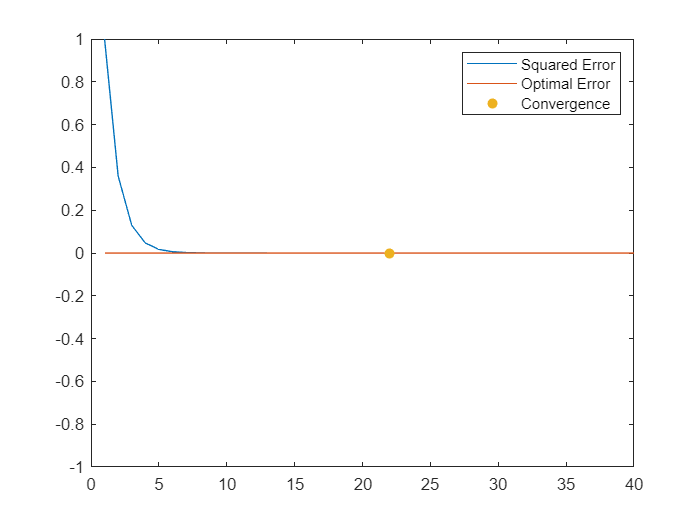

% plotting error history
plot(error_hist)
hold on
plot(zeros([1, 40]))
ylim([-max(error_hist) max(error_hist)])
scatter(iteration, error_hist(iteration), 'filled')
legend('Squared Error', 'Optimal Error', 'Convergence')
hold off

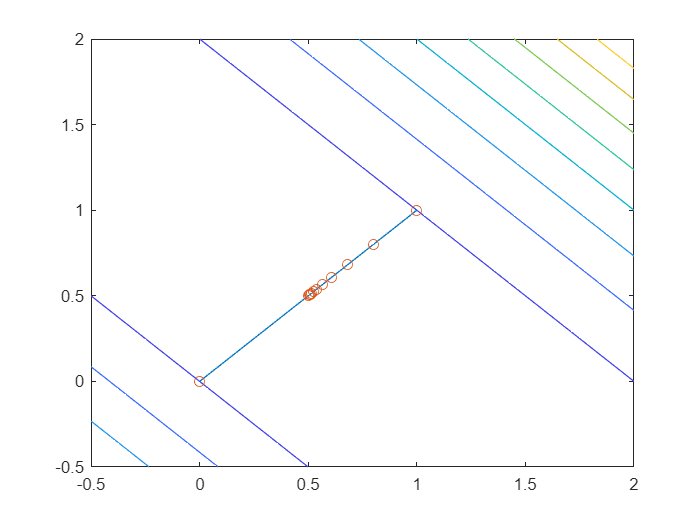

% sketching the trajectory on the contour plot
syms x1 x2 real
X = [x1; x2];
fx = 1 - 2*X'*[1; 1] + X'*[1 1; 1 1]*X;
fcontour(fx,[-0.5 2 -0.5 2])
hold on
plot(x_hist(1,:), x_hist(2,:));
hold on
scatter(x_hist(1,:), x_hist(2,:));
hold off

The decision boundary is calculated by setting the output of the network to 0:


$${X^* }^T p=0\to \left\lbrack 0\ldotp 5,0\ldotp 5\right\rbrack {\left\lbrack p_1 ,p_2 \right\rbrack }^T =0\to p_1 =-p_2$$


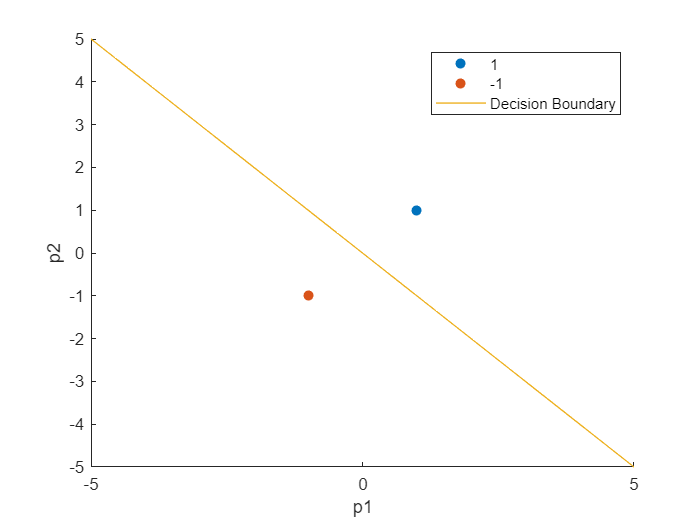

% sketching the decision boundary
scatter(patterns(1,1), patterns(2,1), 'filled')
hold on
scatter(patterns(1,2), patterns(2,2), 'filled')
hold on
syms p2 real
fplot(-p2)
legend('1', '-1', 'Decision Boundary')
xlabel('p1')
ylabel('p2')

As we can see, in minimizing the squared error between the patterns, the decision boundary seems to have passed from between the patterns in such a way that halves the distance between them, effectively putting as much distance as possible between both patterns.

## v.

As we can see the algorithm converged to the same $x^*$ (${\left\lbrack 0\ldotp 5\;0\ldotp 5\right\rbrack }^T$ for both runs) which is expected because the convergence of the LMS algorithm is irrespective of the initial choice for the weights. Although the trajectory looks slightly different at first, the algorithm quickly converges to the same path after a few iterations.